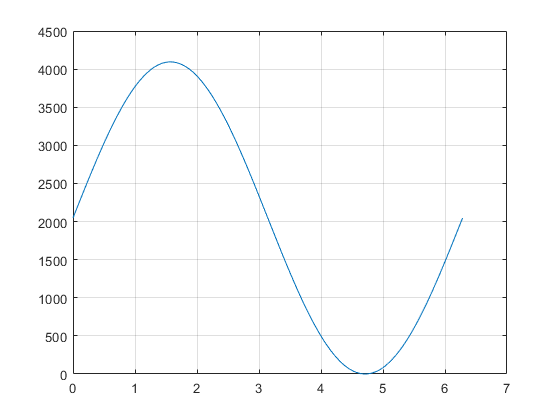

clear; clc;   % Clear The Previous Points
Ns     = 128; % Set The Number of Sample Points
RES    = 12;  % Set The DAC Resolution
OFFSET = 0;   % Set An Offset Value For The DAC Output
%------------[ Calculate The Sample Points ]-------------
T = 0:((2*pi/(Ns-1))):(2*pi);
Y = sin(T);
Y = Y + 1;    
Y = Y*((2^RES-1)-2*OFFSET)/(2+OFFSET); 
Y = round(Y);                  
plot(T, Y); 
grid

%--------------[ Print The Sample Points ]---------------
fprintf('%d, %d, %d, %d, %d, %d, %d, %d, %d, %d, %d, %d, %d, %d, %d, \n', Y);

2048, 2149, 2250, 2350, 2450, 2549, 2646, 2742, 2837, 2929, 3020, 3108, 3193, 3275, 3355, 
3431, 3504, 3574, 3639, 3701, 3759, 3812, 3861, 3906, 3946, 3982, 4013, 4039, 4060, 4076, 
4087, 4094, 4095, 4091, 4082, 4069, 4050, 4026, 3998, 3965, 3927, 3884, 3837, 3786, 3730, 
3671, 3607, 3539, 3468, 3394, 3316, 3235, 3151, 3064, 2975, 2883, 2790, 2695, 2598, 2500, 
2400, 2300, 2199, 2098, 1997, 1896, 1795, 1695, 1595, 1497, 1400, 1305, 1212, 1120, 1031, 
944, 860, 779, 701, 627, 556, 488, 424, 365, 309, 258, 211, 168, 130, 97, 
69, 45, 26, 13, 4, 0, 1, 8, 19, 35, 56, 82, 113, 149, 189, 
234, 283, 336, 394, 456, 521, 591, 664, 740, 820, 902, 987, 1075, 1166, 1258, 
1353, 1449, 1546, 1645, 1745, 1845, 1946, 2047, 

%-------------------[ Other Examples To Try ]-------------------
%  Y = diric(T, 13);     % Periodic Sinc
%  Y = sawtooth(T)       % Sawtooth
%  Y = sawtooth(T, 0.5); % Triangular